Comparación entre formas de hacer la convolución 

Ej 1.Sea la secuencia x[n] = {0, 1, 2, 3, 2, 1, 0, 0, 0, 1, 2, 4, 2, 1, 0, 0, 0, 1, 2, 3} que pasa por el sistema diferenciador h[n] = {1, 1}, con lo que y[n] = x[n] - x[n -1] 

a)Calculad la salida usando la diferencia entre secuencias, con la convoluci´on lineal, con la convoluci´on circular y  con la DFT 

b) Observad que pasa en los extremos 

Si hciese la convolucion con una longitud de 20, observaría que ocurre algo extraño porque para que salga bien, es necesario que añadamos un valor al inicio de cada secuencia.

**Diferencia entre secuencias**

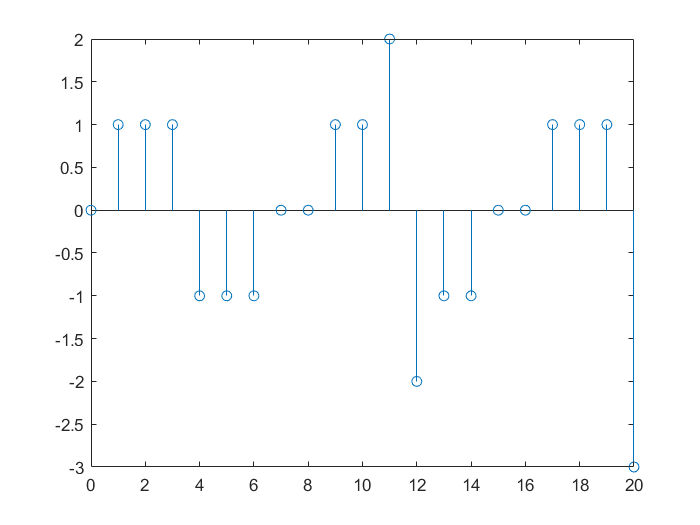

x1= [0, 1, 2, 3, 2, 1, 0, 0, 0, 1, 2, 4, 2, 1, 0, 0, 0, 1, 2, 3]; %Nx=20
h1=[+1,-1]; %Nh=2
%Nx+Nh-1=21 longitud de la nueva secuencia
xa=[x1,0]; %x[n]=xa=[0, 1, 2, 3, 2, 1, 0, 0, 0, 1, 2, 4, 2, 1, 0, 0, 0, 1, 2, 3,0] añado 0 al final
xb=[0,x1]; %x[n-1]=xb=[0,0, 1, 2, 3, 2, 1, 0, 0, 0, 1, 2, 4, 2, 1, 0, 0, 0, 1, 2, 3] añado 0 al inicio
convdif=xa-xb;
n=[0:20];
stem(n,convdif) %deben ser siempre dos variables, no puedo poner 21 

**Convolucion lineal**

convlin=conv(x1,h1);
stem(n,convlin)

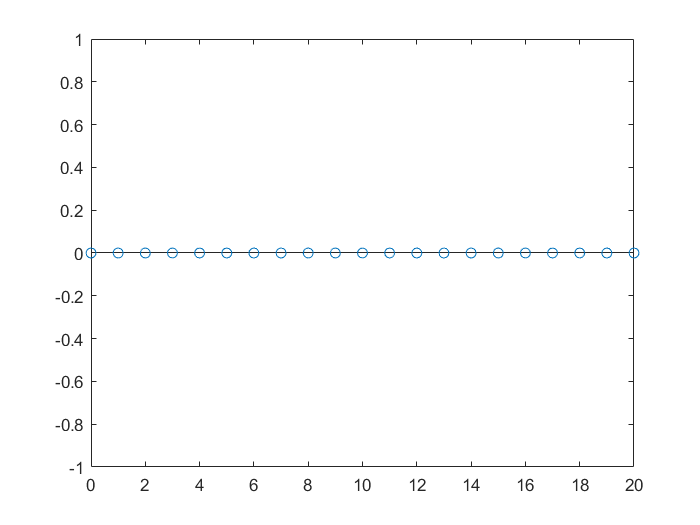

stem(n,convdif-convlin) %Comparo las dos funciones anteriores y como son iguales, da 0

**Convolucion circular**

convcirc=cconv(x1,h1,21); %la ultima coordenada es siempre un numero
stem(n,convcirc)

**DFT**

convdft=ifft(fft(x1,21).*fft(h1,21)); %pongo(x1,21) para que x la extienda hasta longitud 21
stem(n,convdft)

c) Calculad la salida dividiendo la señal de entrada en bloques de longitud 10 y usando la DFT

Nuestros bloques son de 10 pero siempre van a tener una longitud de +1

xt1=[0, 0, 1, 2, 3, 2, 1, 0, 0, 0, 1]; 
xt2=[1, 2, 4, 2, 1, 0, 0, 0, 1, 2, 3];
xt3=[3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];

%empleando la DFT
yt1=ifft(fft(xt1).*fft(h1,11));
yt2=ifft(fft(xt2).*fft(h1,11));
yt3=ifft(fft(xt3).*fft(h1,11));
convbloques=[yt1(2:11),yt2(2:11),yt3(2)] %ojo la salida del 3 

convbloques =    -0.0000    1.0000    1.0000    1.0000   -1.0000   -1.0000   -1.0000    0.0000    0.0000    1.0000    1.0000    2.0000   -2.0000   -1.0000   -1.0000    0.0000    0.0000    1.0000    1.0000    1.0000   -3.0000


stem(n,convbloques)

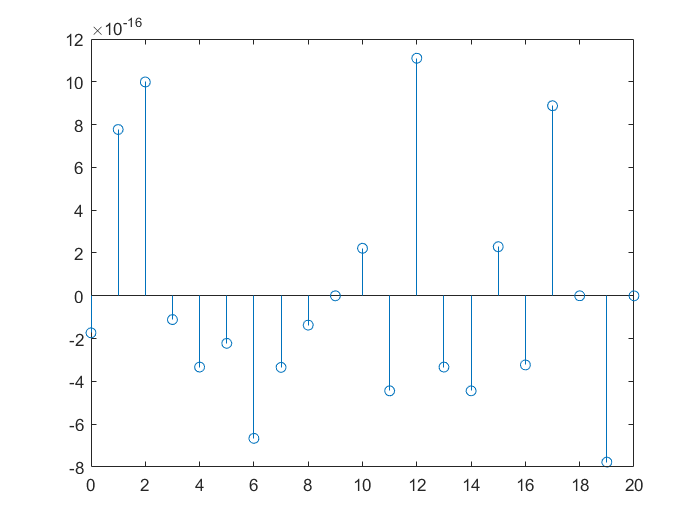

stem(n,convcirc-convbloques) %para comparar

EJ 2. Sea la secuencia x[n] = cos(0,1pi n) que pasa por el mismo sistema diferenciador h[n] = {1, 1} 

a)Usando N = 40, calculad la salida usando la diferencia entre secuencias, con la convoluci´on lineal, con la convolución circular y con la DFT Observad de nuevo qu´e pasa en los extremos. ¿Cuántos valores son correctos? 

b)Con la DFT determinad la frecuencia discreta del coseno, su amplitud y la resoluci´on de frecuencia 

c)Calculad la salida dividiendo la se˜nal de entrada en bloques de longitud 15 y usando la DFT

**Diferencia entre secuencias**

n2=0:39 %para numero enteros no hace falta linspace, solo para frecuencias y etc

n2 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39


x2=cos(0.1*pi*n2)

x2 =     1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511


xa2=[x2,0]; %si tuviese que añadir dos ceros tendria que poner [zero(1,Nh-1)] el primer 1 indica en fila
xb2=[0,x2]; 
convdif2=xa2-xb2;
n2ext=0:40

n2ext =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


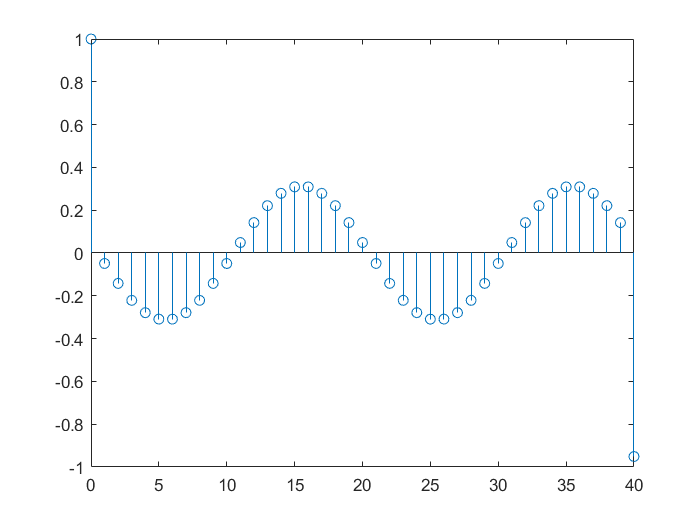

stem(n2ext,convdif2) 

**Convolucion lineal**

convlin2=conv(x2,h1);
stem(n2ext,convlin2) %ojo n2ext

**Convolucion circular**

convcirc2=cconv(x2,h1);
stem(n2ext,convcirc2) %ojo n2ext

**DFT**

h2=[1,-1];
conv2dft=ifft(fft(x2,41).*fft(h2,41)); %pongo(x2,41) para que x la extienda hasta longitud 41
%esto seria la salida del filtro
X2=fft(x2,41)

X2 =    0.0000 + 0.0000i   0.3189 - 0.0523i  19.4763 + 2.8538i  -1.7415 - 0.6415i  -1.1521 - 0.6811i  -0.9032 - 0.7670i  -0.7202 - 0.8517i  -0.5541 - 0.9239i  -0.3914 - 0.9787i  -0.2287 - 1.0133i  -0.0661 - 1.0261i   0.0944 - 1.0162i   0.2502 - 0.9837i   0.3984 - 0.9289i   0.5361 - 0.8531i   0.6603 - 0.7579i   0.7682 - 0.6453i   0.8577 - 0.5179i   0.9266 - 0.3787i   0.9734 - 0.2308i   0.9970 - 0.0775i   0.9970 + 0.0775i   0.9734 + 0.2308i   0.9266 + 0.3787i   0.8577 + 0.5179i   0.7682 + 0.6453i   0.6603 + 0.7579i   0.5361 + 0.8531i   0.3984 + 0.9289i   0.2502 + 0.9837i   0.0944 + 1.0162i  -0.0661 + 1.0261i  -0.2287 + 1.0133i  -0.3914 + 0.9787i  -0.5541 + 0.9239i  -0.7202 + 0.8517i  -0.9032 + 0.7670i  -1.1521 + 0.6811i  -1.7415 + 0.6415i  19.4763 - 2.8538i   0.3189 + 0.0523i


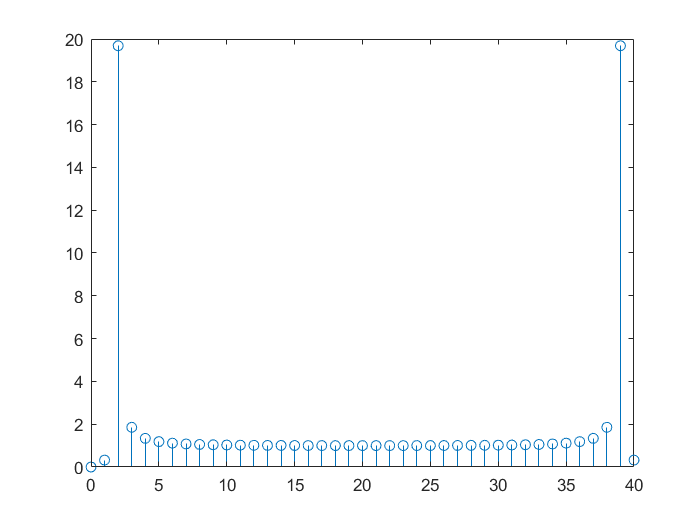

stem(n2ext,abs(X2))

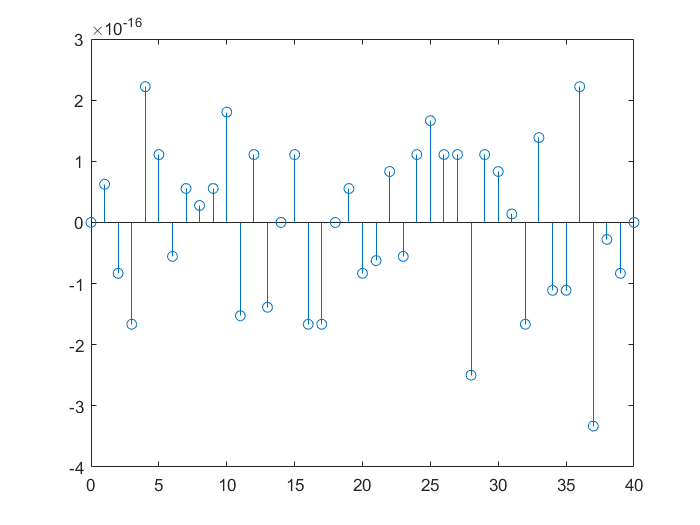

stem(n2ext,convdif2-conv2dft)

b)Con la DFT determinad la frecuencia discreta del coseno, su amplitud y la resolución de frecuencia

[X2ord,ind]=sort(abs(X2),'descend')

X2ord =    19.6843   19.6843    1.8559    1.8559    1.3384    1.3384    1.1849    1.1849    1.1154    1.1154    1.0774    1.0774    1.0541    1.0541    1.0388    1.0388    1.0282    1.0282    1.0206    1.0206    1.0150    1.0150    1.0108    1.0108    1.0076    1.0076    1.0051    1.0051    1.0033    1.0033    1.0019    1.0019    1.0010    1.0010    1.0003    1.0003    1.0000    1.0000    0.3231    0.3231         0


ind =      3    40     4    39     5    38     6    37     7    36     8    35     9    34    10    33    11    32    12    31    13    30    14    29    15    28    16    27    17    26    18    25    19    24    20    23    21    22     2    41     1


omegak=(3/40)*2*pi %%Frecuencia=2pik/N %esta mal, la k=2

omegak = 0.4712

resol=(2*pi)/40 %%resolucion=2pi/N

resol = 0.1571

amplitud=19.6843*(2/40)%%amplitud=2valormaxk/N

amplitud = 0.9842

c)Calculad la salida dividiendo la señal de entrada en bloques de longitud 15 y usando la DFT

n2_1=-1:14; %%genero n de longitud 16
n2_2=14:29; %%siempre tengo en cuenta el valor anterior
n2_3=29:44;
x2_1=cos(0.1*pi*n2_1)

x2_1 =     0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090


x2_2=cos(0.1*pi*n2_2)

x2_2 =    -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511


x2_3=cos(0.1*pi*n2_3)

x2_3 =    -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


y2_1=ifft(fft(x2_1).*fft(h2,16));
y2_2=ifft(fft(x2_2).*fft(h2,16));
y2_3=ifft(fft(x2_3).*fft(h2,16));
convbloques2=[y2_1(2:16),y2_2(2:16),y2_3(2:11)] %porque yo quiero una longitud de 40,

convbloques2 =     0.0489   -0.0489   -0.1420   -0.2212   -0.2788   -0.3090   -0.3090   -0.2788   -0.2212   -0.1420   -0.0489    0.0489    0.1420    0.2212    0.2788    0.3090    0.3090    0.2788    0.2212    0.1420    0.0489   -0.0489   -0.1420   -0.2212   -0.2788   -0.3090   -0.3090   -0.2788   -0.2212   -0.1420   -0.0489    0.0489    0.1420    0.2212    0.2788    0.3090    0.3090    0.2788    0.2212    0.1420


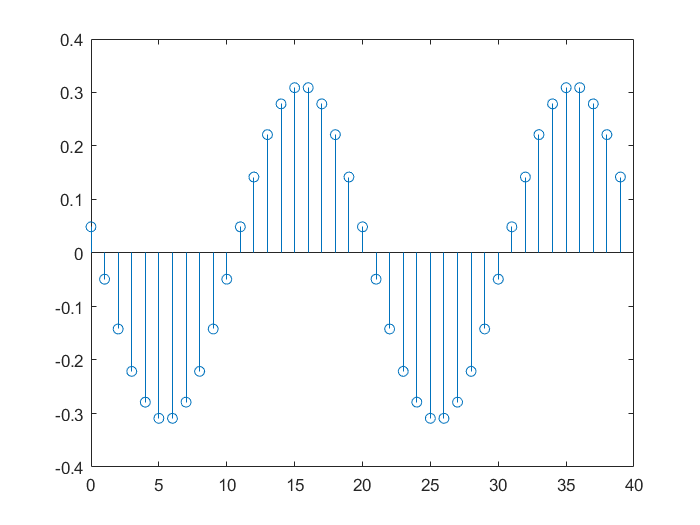

%los demas valores no me interesan
stem(n2,convbloques2) %representan con n2=40

EJ 3. DFT de la respuesta de un sistema 

a)Calcular la salida de x[n]=3cos(0, 5pin + 60)+2sen(0,3pin) con un sistema h[n]=0,5^|n| *cos(0,1pin) usando la DFT 

n3=0:20;
x3=3*cos(0.5*pi.*n3+pi/3)+2*sin(0.3*pi.*n3)

x3 =     1.5000   -0.9800    0.4021    3.2161    0.3244   -4.5981   -2.6756    3.2161    3.4021   -0.9800   -1.5000    0.9800   -0.4021   -3.2161   -0.3244    4.5981    2.6756   -3.2161   -3.4021    0.9800    1.5000


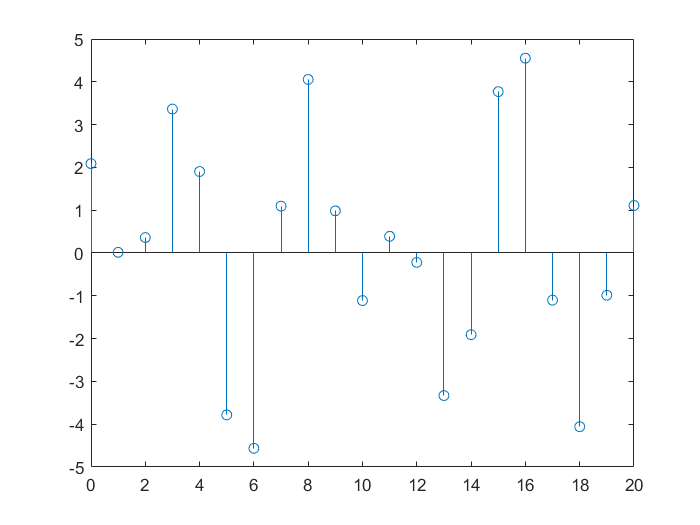

h3=0.5.^abs(n3).*cos(0.1*pi.*n3); %%no causal, tiene valores negativos y positivos
y3=ifft(fft(x3,21).*fft(h3,21));
stem(n3,y3)

b) Con la DFT determinad la frecuencia discreta del coseno, su amplitud y la resoluci´on de frecuencia

X3=fft(x3,21)

X3 =    1.5000 + 0.0000i   1.5722 - 0.0163i   1.9741 - 0.5142i   9.6997 -15.1458i  -1.7620 + 8.6064i  -6.7569 +28.9150i   3.2958 - 8.0040i   2.0315 - 2.9050i   1.7365 - 1.4846i   1.6254 - 0.7510i   1.5837 - 0.2324i   1.5837 + 0.2324i   1.6254 + 0.7510i   1.7365 + 1.4846i   2.0315 + 2.9050i   3.2958 + 8.0040i  -6.7569 -28.9150i  -1.7620 - 8.6064i   9.6997 +15.1458i   1.9741 + 0.5142i   1.5722 + 0.0163i


[X3ord,ind]=sort(abs(X3),'descend') %esto nos dice que el max se alcanza en el indice 6

X3ord =    29.6940   29.6940   17.9855   17.9855    8.7849    8.7849    8.6560    8.6560    3.5448    3.5448    2.2846    2.2846    2.0399    2.0399    1.7905    1.7905    1.6007    1.6007    1.5723    1.5723    1.5000


ind =      6    17     4    19     5    18     7    16     8    15     9    14     3    20    10    13    11    12     2    21     1


omega3k=(6/21)*2*pi %%Frecuencia=2pik/N en radianes me lo calcula 

omega3k = 1.7952

resol=(2*pi)/21 %%resolucion=2pi/N

resol = 0.2992

amplitud=29.6940*(2/21)%

amplitud = 2.8280

 c) Compararlo con el sistema usando h[n]=0,5|n| cos(0,1pin)u[n]